           В прямоугольном волноводе сечением 23х10 мм^2 распространяется волна типа Н10. Волновод заполнен диэлектриком с относительной диэлектрической проницаемостью *ε**r *= (1+0,2·M+0,01·N) и относительной магнитной проницаемостью *µ**r *= 1. Амплитуда напряженности электрического поля в центре волновода равна (M+2,2·N)·10^5 В/м. Частота колебаний (1+0,005·N)·10 ГГц. Записать выражения для составляющих поля волны, определить мощность, передаваемую волной, фазовую и групповую скорости, длину волны в волноводе, а также плотности поверхностных токов на стенках (плотности поверхностных токов записать в виде выражений для четырех стенок).

- **КОНСТАНТЫ**

c = 3e8

c = 300000000

e0 = 8.85e-12

e0 = 8.8500e-12

m0 = 1.25e-6

m0 = 1.2500e-06

- **ДАНО**

M = 5; N = 12;
a = 0.023

a = 0.0230

b = 0.01

b = 0.0100

er = 1 + 0.25*M + 0.01*N

er = 2.3700

mr = 1

mr = 1

f = (1 + 0.008*N)*10*1e9

f = 1.0960e+10

Em = (M + 2.4*N)*1e4

Em = 338000

- **НАЙТИ**

 Записать выражения для составляющих поля волны

 определить мощность, передаваемую волной

 фазовую и групповую скорости

 длину волны в волноводе  

плотности поверхностных токов на стенках (плотности поверхностных токов записать в виде выражений для четырех стенок).

- **РЕШЕНИЕ**

Поле $H_{10}$ в прямоугольном волноводе:


$$\dot{H_{\textrm{mz}} } =H\cdot \cos \left(\frac{\pi x}{a}\right)\cdot e^{-{\textrm{jk}}_0 z}$$



$$\dot{H_{\textrm{mx}} } =i\cdot \frac{2a}{\lambda }\cdot \sqrt{1-{\left(\frac{\lambda }{2a}\right)}^2 }\cdot H\cdot \sin \left(\frac{\pi x}{a}\right)\cdot e^{-{\textrm{jk}}_0 z}$$



$$\dot{E_{\textrm{my}} } =-i\cdot \frac{2a}{\lambda }\cdot Z_0 \cdot \sin \left(\frac{\pi x}{a}\right)\cdot e^{-{\textrm{jk}}_0 z}$$



$$\dot{H_{\textrm{my}} } =\dot{E_{\textrm{mx}} } =\dot{E_{\textrm{mz}} } =0$$


Критическая длина волны для поля $H_{10}$ в прямоугольном волноводе


$$\lambda_{\mathrm{кр}} =2a\Longrightarrow \lambda_{\mathrm{кр}} =2\cdot 0,023=0,046\;\left\lbrack м\right\rbrack \ldotp$$


lamda_kra = 2*a

lamda_kra = 0.0460

Длина волны в среде волновода, при условии что она не ограничена


$$\lambda =\frac{\lambda_0 }{\sqrt{\varepsilon_r }},$$


где $\lambda_0$ - длина волны в воздухе.


$$\lambda_0 =\frac{с}{f}=\frac{3\cdot {10}^8 }{1,096\cdot {10}^{10} }=0,027\;\left\lbrack м\right\rbrack ,$$


lamda_0 = c/f

lamda_0 = 0.0274


$$\lambda =\frac{0,0283}{\sqrt{2,12}}=0,017\;\left\lbrack м\right\rbrack \ldotp$$


lamda = lamda_0 / sqrt(er)

lamda = 0.0178

Длина волны в волноводе 


$$\Lambda =\frac{\lambda }{\sqrt{1-{\left(\frac{\lambda }{\lambda_{\mathrm{кр}} }\right)}^2 }}=\frac{0,017}{\sqrt{1-{\left(\frac{0,017}{0,046}\right)}^2 }}=0,019\left\lbrack м\right\rbrack \ldotp$$


Lamda = lamda / sqrt(1 - (lamda/lamda_kra)^2)

Lamda = 0.0193

Продольная постоянная распространения 


$$k_0 =k\cdot \sqrt{1-{\left(\frac{\lambda }{\lambda_{\textrm{кр}} }\right)}^2 }=\frac{2\pi }{\lambda }\cdot \sqrt{1-{\left(\frac{\lambda }{\lambda_{\textrm{кр}} }\right)}^2 },$$



$$k_0 =\frac{2\pi }{0,017}\cdot \sqrt{1-{\left(\frac{0,017}{0,046}\right)}^2 }=325,916\;\left\lbrack \frac{1}{м}\right\rbrack \ldotp$$


k_0 = (2*pi/lamda)*sqrt(1 - (lamda/lamda_kra)^2)

k_0 = 325.9158

Характеристическое сопротивление среды, заполняющие волновод


$$Z_0 =\sqrt{\frac{\mu_a }{\varepsilon_a }}=\sqrt{\frac{\mu_0 }{\varepsilon_r \varepsilon_0 }}=\sqrt{\frac{1,25\cdot {10}^6 }{2,37\cdot 8,85\cdot {10}^{-12} }}=244,12\;\left\lbrack \mathrm{Ом}\right\rbrack \ldotp$$


Z_0 = sqrt(m0/(er*e0))

Z_0 = 244.1233

Характеристическое сопротивление волновода для волны $H_{10}$


$$Z_{\mathrm{OH}} =\frac{Z_0 }{\sqrt{1-{\left(\frac{\lambda }{2a}\right)}^2 }}=\frac{244,12}{\sqrt{1-{\left(\frac{0,017}{2\cdot 0,023}\right)}^2 }}=264,69\;\left\lbrack \mathrm{Ом}\right\rbrack \ldotp$$


Z_OH = Z_0 / sqrt(1 - (lamda/(2*a))^2)

Z_OH = 264.6958

Определим коэффицент H


$$E_0 =-\frac{240\pi a}{\lambda \sqrt{\varepsilon_r }}H\Longrightarrow H=-\frac{\lambda \sqrt{\varepsilon_r }}{240\pi a}E_0 ,$$



$$H=-\frac{0,017\cdot \sqrt{2,37}}{240\cdot \pi \cdot 0,023}\cdot 3,38\cdot {10}^6 =-533\;\left\lbrack \frac{A}{м}\right\rbrack \ldotp$$


H = -(lamda*sqrt(er)*Em)/(240*pi*a)

H = -533.5049

Выразим для составляющих поля в численном виде


$$\dot{H_{\mathrm{mz}} } =\left(-533\right)\cdot \cos \left(\frac{\pi \cdot x}{0,023}\right)\cdot e^{-j\cdot 325,91\cdot z} \;\left\lbrack \frac{A}{м}\right\rbrack$$



$$\dot{H_{\mathrm{mx}} } =i\cdot \frac{2\cdot 0,023}{0,017}\cdot \sqrt{1-{\left(\frac{0,017}{2\cdot 0,023}\right)}^2 }\cdot \left(-533\right)\;\cdot \sin \left(\frac{\pi x}{0,023}\right)\cdot e^{-j\cdot 325,91\cdot z} \;\left\lbrack \frac{A}{м}\right\rbrack ,$$



$$\dot{H_{\mathrm{mx}} } =i\cdot \left(-1340\right)\cdot \sin \left(\frac{\pi x}{0,023}\right)\cdot e^{-j\cdot 325,91\cdot z} \;\left\lbrack \frac{A}{м}\right\rbrack ,$$



$$\dot{E_{\mathrm{my}} } =-i\cdot \frac{2\cdot 0,023}{0,017}\cdot 244,12\cdot \sin \left(\frac{\pi \cdot x}{0,023}\right)\cdot e^{-j\cdot 325,91\cdot z} \;\left\lbrack \frac{В}{м}\right\rbrack ,$$



$$\dot{E_{\mathrm{my}} } =-i\cdot 660,56\cdot \sin \left(\frac{\pi \cdot x}{0,023}\right)\cdot e^{-j\cdot 325,91\cdot z} \;\left\lbrack \frac{В}{м}\right\rbrack ,$$



$$\dot{H_{\textrm{my}} } =\dot{E_{\textrm{mx}} } =\dot{E_{\textrm{mz}} } =0\ldotp$$


Мощность, передаваемая волноводом


$$P_{\textrm{ср}} =\frac{\textrm{ab}\sqrt{1-{\left(\frac{\lambda }{2a}\right)}^2 }}{4Z_0 }E_0^2 ,$$



$$P_{\mathrm{ср}} =\frac{0,023\cdot 0,01\cdot \sqrt{1-{\left(\frac{0,017}{2\cdot 0,023}\right)}^2 }}{4\cdot 244,12}\cdot {\left(3,38\cdot {10}^6 \right)}^2 =24817\;\left\lbrack \mathrm{Вт}\right\rbrack \ldotp$$


P = (a*b*sqrt(1 - (lamda/(2*a))^2)*Em^2)/(4*Z_0)

P = 2.4817e+04

Фазовая и групповая скорость


$$\upsilon_ф =\frac{\frac{c}{\sqrt{\varepsilon_r }}}{\sqrt{1-{\left(\frac{\lambda }{\lambda_{\mathrm{кр}} }\right)}^2 }}=\frac{\frac{3\cdot {10}^8 }{\sqrt{2,37}}}{\sqrt{1-{\left(\frac{0,017}{0,046}\right)}^2 }}=2,11\cdot {10}^8 \;\left\lbrack \frac{м}{с}\right\rbrack ,$$


V_phaza = (c/sqrt(er))/sqrt(1 - (lamda/lamda_kra)^2)

V_phaza = 2.1129e+08


$$\upsilon_г =\frac{c}{\sqrt{\varepsilon_r }}\cdot \sqrt{1-{\left(\frac{\lambda }{\lambda_{\mathrm{кр}} }\right)}^2 }=\frac{3\cdot {10}^8 }{\sqrt{2,37}}\cdot \sqrt{1-{\left(\frac{0,017}{0,046}\right)}^2 }=1,79\cdot {10}^8 \;\left\lbrack \frac{м}{с}\right\rbrack \ldotp$$


V_grup = (c/sqrt(er)) * sqrt(1 - (lamda/lamda_kra)^2)

V_grup = 1.7973e+08

Плотность поверхностных токов


$$\overrightarrow{J_{\textrm{пов}} } =\left\lbrack \overrightarrow{n_0 } \overrightarrow{H} \right\rbrack ,$$


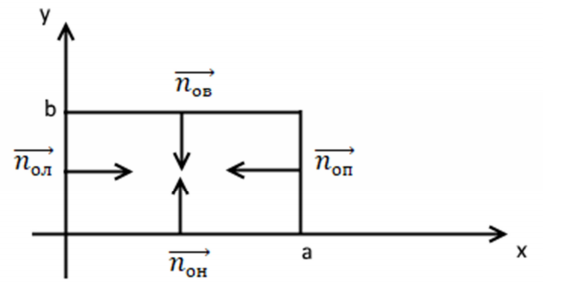

Рисунок 1 - Поверхностные токи.

1) На левой стенке


$$\overrightarrow{n_{\textrm{ол}} } =\left\lbrack 0,\;1,\;0\right\rbrack$$


Составляющие поля (х = 0)


$$\dot{H_{\mathrm{mz}} } |_{x=0} =\left(-533\right)\cdot e^{-j\cdot 325,91\cdot z} \left\lbrack \frac{А}{м}\right\rbrack ,$$



$$\dot{H_{\mathrm{mx}} } |_{x=0} =0\left\lbrack \frac{А}{м}\right\rbrack ,$$



$$\dot{H_{\mathrm{my}} } |_{x=0} =0\left\lbrack \frac{А}{м}\right\rbrack \ldotp$$
 


$$\overrightarrow{j_{\mathrm{пов}\ldotp л\ldotp } } =\left\lbrack \begin{array}{ccc}
\overrightarrow{e_1 }  & \overrightarrow{e_2 }  & \overrightarrow{e_3 } \\
1 & 0 & 0\\
0 & 0 & \dot{H_{\mathrm{mz}} } 
\end{array}\right\rbrack =-\dot{H_{\mathrm{mz}} } \cdot \overrightarrow{e_2 } \Longrightarrow$$



$$\overrightarrow{j_{\mathrm{пов}\ldotp л\ldotp } } =533\cdot e^{-j\cdot 325,91\cdot z} \cdot \overrightarrow{e_2 } \;\left\lbrack \frac{А}{м}\right\rbrack \ldotp$$


2) На правой стенке


$$\overrightarrow{n_{\textrm{оп}} } =\left\lbrack -1,0,\;0\right\rbrack$$


Составляющие поля (х = a)


$$\dot{H_{\mathrm{mz}} } |_{x=a} =533\cdot e^{-j\cdot 325,91\cdot z} \;\left\lbrack \frac{А}{м}\right\rbrack ,$$



$$\dot{H_{\mathrm{mх}} } |_{x=a} =0\;\left\lbrack \frac{А}{м}\right\rbrack ,$$



$$\dot{H_{\mathrm{my}} } |_{x=a} =0\;\left\lbrack \frac{А}{м}\right\rbrack \ldotp$$
 


$$\overrightarrow{j_{\mathrm{пов}\ldotp п\ldotp } } =\left\lbrack \begin{array}{ccc}
\overrightarrow{e_2 }  & \overrightarrow{e_2 }  & \overrightarrow{e_3 } \\
-1 & 0 & 0\\
0 & 0 & \dot{H_{\mathrm{mz}} } 
\end{array}\right\rbrack =\dot{-H_{\mathrm{mz}} } \cdot \overrightarrow{e_2 } \Longrightarrow$$



$$\overrightarrow{j_{\mathrm{пов}\ldotp п\ldotp } } =533\cdot e^{-j\cdot 325,91\cdot z} \cdot \overrightarrow{e_2 } \;\left\lbrack \frac{А}{м}\right\rbrack \ldotp$$


3) На верхней стенке


$$\overrightarrow{n_{\textrm{ов}} } =\left\lbrack 0,\;-1,\;0\right\rbrack$$


Составляющие поля не зависят от y


$$\overrightarrow{j_{\mathrm{пов}\ldotp в\ldotp x} } =533\cdot e^{-j\cdot 325,91\cdot z} \;\left\lbrack \frac{А}{м}\right\rbrack ,$$



$$\overrightarrow{j_{\textrm{пов}\ldotp в\ldotp y} } =0\;\left\lbrack \frac{А}{м}\right\rbrack ,$$



$$\overrightarrow{j_{\mathrm{пов}\ldotp в\ldotp z} } =i\cdot \left(-1340\right)\cdot \sin \left(\frac{\pi x}{0,023}\right)\cdot e^{-j\cdot 325,91\cdot z} \;\left\lbrack \frac{А}{м}\right\rbrack \ldotp$$



$$\overrightarrow{j_{\mathrm{пов}\ldotp в\ldotp } } =\left\lbrack \begin{array}{ccc}
\overrightarrow{e_1 }  & \overrightarrow{e_2 }  & \overrightarrow{e_3 } \\
0 & -1 & 0\\
\dot{H_{\mathrm{mx}} }  & 0 & \dot{H_{\mathrm{mz}} } 
\end{array}\right\rbrack =\;-\overrightarrow{e_1 } \dot{H_{\mathrm{mz}} } \;+\overrightarrow{e_3 } \dot{H_{\mathrm{mx}} } \Longrightarrow$$



$$\overrightarrow{j_{\mathrm{пов}\ldotp в\ldotp } } =533\cdot e^{-j\cdot 325,91\cdot z} \overrightarrow{e_1 } +i\cdot 1340\cdot \sin \left(\frac{\pi x}{0,023}\right)\cdot e^{-j\cdot 325,91\cdot z} \overrightarrow{e_3 } \;\left\lbrack \frac{А}{м}\right\rbrack \ldotp$$


4) На нижней стенке


$$\overrightarrow{n_{\textrm{он}} } =\left\lbrack 0,1,0\right\rbrack$$


Составляющие поля не зависят от y


$$\overrightarrow{j_{\mathrm{пов}\ldotp н\ldotp x} } =-533\cdot e^{-j\cdot 325,91\cdot z} \;\left\lbrack \frac{А}{м}\right\rbrack ,$$



$$\overrightarrow{j_{\textrm{пов}\ldotp н\ldotp y} } =0\;\left\lbrack \frac{А}{м}\right\rbrack ,$$



$$\overrightarrow{j_{\mathrm{пов}\ldotp н\ldotp z} } =i\cdot 1340\cdot \sin \left(\frac{\pi x}{0,023}\right)\cdot e^{-j\cdot 325,91\cdot z} \;\left\lbrack \frac{А}{м}\right\rbrack \ldotp$$



$$\overrightarrow{j_{\mathrm{пов}\ldotp н\ldotp } } =\left\lbrack \begin{array}{ccc}
\overrightarrow{e_1 }  & \overrightarrow{e_2 }  & \overrightarrow{e_3 } \\
0 & 1 & 0\\
\dot{H_{\mathrm{mx}} }  & 0 & \dot{H_{\mathrm{mz}} } 
\end{array}\right\rbrack =\;\overrightarrow{e_1 } \dot{H_{\mathrm{mz}} } -\overrightarrow{e_3 } \dot{H_{\mathrm{mx}} } \Longrightarrow$$



$$\overrightarrow{j_{\mathrm{пов}\ldotp н\ldotp } } =i\cdot 1340\cdot \sin \left(\frac{\pi x}{0,023}\right)\cdot e^{-j\cdot 325,91\cdot z} \cdot \overrightarrow{e_1 } +533\cdot e^{-j\cdot 325,91\cdot z} \cdot \overrightarrow{e_3 } \;\left\lbrack \frac{А}{м}\right\rbrack \ldotp$$
